# Region Segmentation 

[⇦ Main Menu](matlab:open('..\MainMenu.mlx'))

An introduction to region-based image segmentation techniques. 

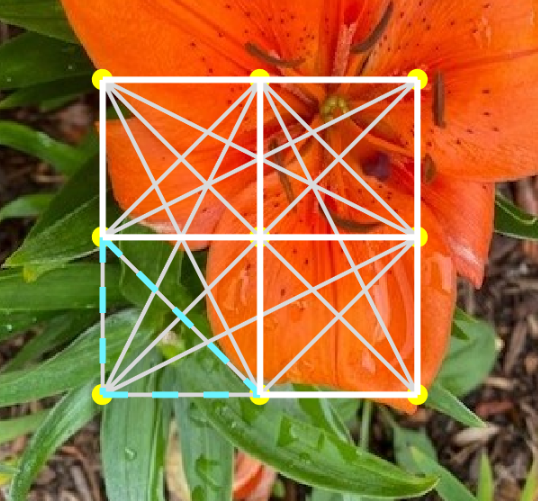

An overview of region segmentation techniques including, histogram, k-means clustering, and graph-cut algorithms.

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

  **Pro-tip**. Review [Machine Learning Methods: Clustering ](https://www.mathworks.com/matlabcentral/fileexchange/135381-machine-learning-methods-clustering)to learn how clustering works and to learn the fundamentals of k-means clustering.

## Region Segmentation

Region-based segmentation is an image processing technique that groups pixels into regions based on specific criteria such as color, intensity, or texture. The primary objective is to partition an image into meaningful segments where pixels within the same region exhibit similar properties. For example, in a color image, all pixels within a region might share similar colors, creating a coherent segment.

For instance, in an MRI scan of the brain, region-based segmentation can help distinguish between different tissue types by grouping pixels with similar intensity values. This segmentation is essential for diagnosing conditions, planning surgeries, and monitoring treatment progress.

### Histogram-Based Segmentation for a Simple Image

**Histogram-based segmentation** is a technique used in image processing to partition or segment an image into different regions based on the intensity values of its pixels. This method involves creating a histogram of the pixel intensities and identifying peaks and valleys in the histogram to determine thresholds. These thresholds are then used to segment the image into distinct regions. The main advantage of histogram-based segmentation is its simplicity and efficiency, making it suitable for images with well-defined intensity distributions. 

  **Try**. View the toy image and its corresponding histogram by pressing the button below.

 
Toy=imread("Toy.jpg");
% ToyG=im2gray(Toy);
figure
imshow(Toy)
title("Toy Image")
figure
HistDisp(Toy);
title("Histogram of Toy Image"); % Add a title to the histogram

We can view pixel intensity ranges for the 3 sets of pixels ranges in our image. 

  **Try**. Display the histogram for each specified range within the pixel regions of the toy image.

% Display histogram of toy image with intensity range 100 to 150
if ~exist("ToyG","var")
    Toy = imread("Toy.jpg");
    ToyG = im2gray(Toy);
end

figure

Range = "Select";
if strcmp(Range,"Select")
    BinSz=1;
    DispHist(Range,ToyG,BinSz);
    title("Histogram of Toy Image for "+ Range+" Pixel Range"); % Add a title to the histogram
else
    disp("Select a valid option.")
end

 **Exercise 1. **Which bin range is associated with the square object in the toy image?

**Solution:**

CheckAnswer("exercise1","Select")  

### Histogram-Based Segmentation for a Complex Image

Though histogram-based segmentation is easy for well-defined regions, is is more difficult for images with overlapping intensity ranges or require more complex segmentation criteria. What if the image is not quite as simple? If we increase the complexity of our toy image by adding noise, then the histogram is more spread out. Can you distinguish between the regions of the histogram now? 

 
if ~exist("ToyG","Var")
    ToyG = imread("Toy.jpg");
    ToyG = im2gray(ToyG);
end
ToyNoise = imnoise(ToyG,"gaussian",0.3);
figure
imshow(ToyNoise)
title("Complex Image")
figure
HistDisp(ToyNoise);
title("Histogram of Noisy Toy Image for "+RangeN+" Pixel Range");

  **Try**. Display the histogram for each specified range within the pixel regions of the toy image.

if ~exist("ToyNoise","Var")
    ToyG = imread("Toy.jpg");
    ToyG = im2gray(ToyG);
    ToyNoise = imnoise(ToyG,"gaussian",0.3);
end
figure
RangeN = "Select";
BinSz=10;
DispHist(RangeN,ToyNoise,BinSz);
title("Histogram of Complex Image")

## K-Means Clustering to Segment Simple Images

We need to cluster to find "centers or centroids" that represent different colors or intensities in an image. The **k-means clustering** algorithm accepts a user-chosen value of *k*, the number of clusters. Initially, it randomly selects the centroid locations for each cluster. Then, it assigns each data point to the nearest cluster based on the sum of squared distances (SSD) from the centroids. Due to the random selection of centroids, cluster assignments can vary.

The best cluster centers minimize the SSD between all points and their nearest cluster center, *ci*, using the equation:


$$
SSD = \sum_\text{cluster i} \sum_{x \in \text{cluster i}} (x - c_i)^2$$


Manually determining optimal cluster centers is challenging because we don't know which pixels belong together. **K-means clustering** automates this process by iteratively refining the centroids to minimize the SSD, effectively grouping similar pixels. This is crucial for tasks like image segmentation, where accurately identifying regions with similar colors or intensities is essential.

  **Try**. Perform k-means clustering to segment the Noisy toy image. Select the number of clusters, *k*.

ToyK=imread("Toy.jpg"); % Load image
ImgKmeans = imnoise(ToyK,"gaussian",0.3);

ImgKmeans=ToyK;
ImgKmeans=rgb2lightness(ImgKmeans);
% ImgKmeans=imread("Toy.jpg");
imshow(ImgKmeans,[])
title("Original Image")
% Convert to double for processing
ImgDouble = im2double(ImgKmeans);

K = 4;
[clusterIndices,centroids2] = kmeans(ImgDouble,K, Replicates=10);

% Display results

% Display 2D scatter plot (PCA)
[~,score] = pca(ImgDouble);
clusterMeans = grpstats(score,clusterIndices,"mean");
h = gscatter(score(:,1),score(:,2),clusterIndices);
for i = 1:numel(h)
    h(i).DisplayName = strcat("Cluster",h(i).DisplayName);
end
clear h i
hold on
h = scatter(clusterMeans(:,1),clusterMeans(:,2),50,"x",LineWidth=2);
hold off
h.DisplayName ="Centroids";
clear h clusterMeans
legend;
title("K-Means Clustered Data");
xlabel("First principal component");
ylabel("Second principal component");

## Using Silhouette Plots to Validate K-means Clustering of Simple Images

A silhouette graph is a useful tool for assessing the quality of clusters created by the **k-means clustering** algorithm. It works by calculating a silhouette score for each data point, which ranges from -1 to 1, with higher scores indicating better clustering. The graph plots these scores on the x-axis and lists the data points by cluster on the y-axis. High scores suggest well-clustered points, while low or negative scores indicate points that may be in the wrong cluster or lie between clusters. The width of each cluster in the graph shows the number of points in that cluster. If many points have low or negative scores, it may be necessary to adjust the number of clusters and re-run the k-means clustering.

Key criteria for good silhouette plots include:

- ***Silhouette Scores***: High average scores indicate well-defined clusters.

- ***Separation***: Clear gaps between clusters, showing minimal overlap.

- ***Width***: Uniform widths within each cluster, representing the number of points.

  **Try**. Adjust k-means k-value to obtain the most ideal silhouette graph.

 
% Create silhouette plot to compare the results of cluster data
silhouette(score,clusterIndices,"cityblock");
title("Silhouette Plot for K-means Clustering");
xlabel("Silhouette Value");
ylabel("Cluster Index");
AvgSilVal=mean(clusterIndices);
AvgSilVal=round(AvgSilVal,3,"significant");
disp("The average silhouette value is: "+AvgSilVal)

 **Exercise 2. **How many clusters should you use to segment the toy image?

**Solution:**

CheckAnswer("exercise2","Select")

## K-Means Clustering to Segment Complex Images

  **Try**. Select an image on which to perform k-means clustering.

ImageR = "Select";
if ~strcmp(ImageR,"Select")
    % Load image
    ImageR = imread(ImageR);
    imshow(ImageR);
    title("Original Image");
else
    warning("Select a valid option.")
    return
end

  **Try**. Select the number of clusters, k to perform k-means clustering on your chosen image.

k = 6;
[PixSamp,idx] = PlotKClust(ImageR,k);

## Using Silhouette Plots to Validate K-means Clustering of Complex Images

Remember the key criteria for good silhouette plots. These criteria suggest that the clustering structure is strong and that the chosen *k* effectively captures the natural grouping in the data. If the silhouette plot meets these criteria, it means you have likely chosen a value of *k* that is close to the correct number of clusters for your data.

  **Try**. Evaluate your choice of k used to perform k-means clustering on your chosen image above.

 
%  Create silhouette graph for the clustering (only if clusters are valid)
if numel(unique(idx))>1
    figure;
    silhouette(PixSamp,idx,"cityblock");
    title("Silhouette Plot for K-means Clustering");
    xlabel("Silhouette Value");
    ylabel("Cluster Index");
else
    warning("Silhouette plot cannot be generated with only one cluster.");
end
AvgSilValB = mean(idx);
AvgSilValB = round(AvgSilValB,3,"significant");
disp("The average silhouette value is: "+AvgSilValB)

## Graph-Cut Segmentation

**K-means clustering** is ideal for partitioning data into a predefined number of clusters based on feature similarity. It's commonly used in applications where data can be represented in a feature space, such as color-based image segmentation. However, when the goal is to partition an image into regions with distinct boundaries for precise object delineation, such as segmenting an object from the background, it is best to use **graph-cut segmentation**.

In **graph-cut segmentation**, an image is represented as a graph. Each pixel in the image is treated as a node in this graph. Nodes are connected by edges, which can be weighted to indicate the strength of the connection between nodes. These weights measure the similarity between connected pixels.

The goal is to partition the graph into subgraphs by cutting the edges. Similar pixels should end up in the same segment, while dissimilar pixels should be in different segments. The result of the graph cut is a binary segmentation of the image, classifying each pixel as either foreground or background based on the cut.

** Demonstration**. Visualize the graph-cut segmentation process on a sample image.  

 
GrphImg = imread("FlowerE.jpg"); % Load the image
[ImgHeight, ImageWidth,~] = size(GrphImg); % Get the size of the image

figure;
imshow(GrphImg); % Display the image
hold on; % Keep the image while plotting the graph

% Define the number of rows and columns for the grid
rows = 3;
cols = 3;

% Compute the center of the image
ImgCtrX = ImageWidth/2;
ImgCtrY = ImgHeight/2;

% Compute the center of the grid
GrdCtrX = (cols-1)*100/2;
GrdCtrY = (rows-1)*100/2;

% Offset to align the middle node with the image center
XOffset = ImgCtrX-GrdCtrX;
YOffset = ImgCtrY-GrdCtrY;

% Calculate node positions and center the grid
[x,y] = meshgrid(linspace(0,(cols-1)*100,cols)+XOffset, ...
    linspace(0,(rows-1)*100,rows)+YOffset);

% Flatten the grid for easier handling
x = x(:);
y = y(:);

% Initialize edges list
Edges = [];

% Create standard grid connections (horizontal, vertical, diagonal)
for i = 1:length(x)
    for j = i+1:length(x)
        % Horizontal connections (same row)
        if y(i) == y(j)&&abs(x(i)-x(j)) == 100
            Edges = [Edges;i,j];
            % Vertical connections (same column)
        elseif x(i) == x(j)&&abs(y(i)-y(j)) == 100
            Edges = [Edges;i,j];
            % Diagonal connections (adjacent diagonal nodes)
        elseif abs(x(i)-x(j)) == 100&&abs(y(i)-y(j)) == 100
            Edges = [Edges;i,j];
        end
    end
end

% Add extra custom edges
CustomEdges = [
    1,6;
    1,8;
    4,3;
    4,9;
    2,7;
    3,5;
    5,9;
    6,8;
    7,2;
    8,3;
    9,4
    ];

% Combine standard and custom edges
Edges = [Edges;CustomEdges];

% Remove duplicate edges and self-loops
Edges = unique(sort(Edges,2),"rows");
Edges(Edges(:,1) == Edges(:,2),:) = []; % Ensure no self-loops

title("Image with Nodes and Edges");
pause(2)

% Plot nodes with animation
NodeHandles = gobjects(length(x),1);
title("Drawing Nodes")
drawnow
pause(2)
for i = 1:length(x)
    NodeHandles(i) = scatter(x(i),y(i),100,"yellow","filled");
    text(x(i)+10,y(i),num2str(i),Color="white",FontSize=12,FontWeight="bold",Tag="NodeHandles"); % label nodes
    % end
    drawnow; % Immediately updates the figure
end

for i = 1:length(x)
    delete(findall(gcf,Tag="NodeHandles")); % Delete node labels
end

title("Drawing Edges")
drawnow
pause(2)
for k = 1:size(Edges,1)
    plot([x(Edges(k,1)),x(Edges(k,2))],[y(Edges(k,1)),y(Edges(k,2))],"-",SeriesIndex="none",LineWidth=2);
    drawnow; % Ensures the edge appears immediately
end

title("Creating Subgraph 1 of Similar Edges")% Plot specified connections with one color
pause(2)
SpecialNodes = [2, 3, 6];
specialEdges = any(ismember(Edges, SpecialNodes),2) & all(ismember(Edges,SpecialNodes),2);
for k = find(specialEdges)'
    plot([x(Edges(k,1)),x(Edges(k,2))],[y(Edges(k,1)),y(Edges(k,2))],"--",SeriesIndex=6, LineWidth=3);
end
pause(2)

title("Creating Subgraph 1 of Similar Edges")
pause(2)
% Plot horizontal and vertical connections for other nodes
for k = 1:size(Edges,1)
    if ~specialEdges(k)
        if x(Edges(k,1)) == x(Edges(k,2)) || y(Edges(k,1)) == y(Edges(k,2))
            plot([x(Edges(k,1)),x(Edges(k,2))],[y(Edges(k,1)),y(Edges(k,2))],"-",Color="white",LineWidth=3);
        end
    end

% Finalize the figure
hold off;
title("Image with Nodes and Edges");

% Now highlight the high similarity regions (aka graph cut)


** Demonstration**. Use graph-cut segmentation to segment the flower from the background.

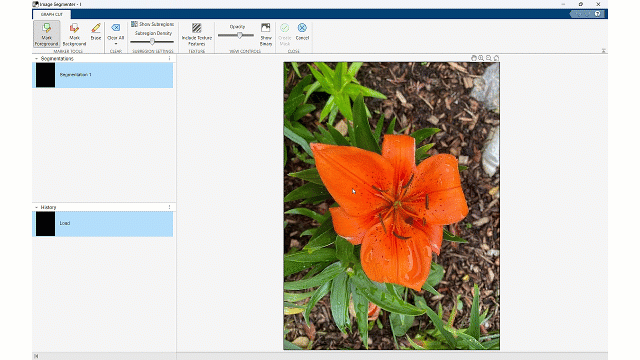

  **Try**. Use graph-cut segmentation to segment the objects (building, glacier, and path) from their respective backgrounds.

- Load image in Image Segmenter App.

- Select the Graph-Cut icon from the Segmentation Tools toolstrip.

- Mark a foreground object by drawing inside the object. 

- Mark a background object by drawing in the background around the object.

- Select Show Binary to display your binary segmented image.

GraphImg = "Select";
if ~strcmp(GraphImg,"Select")
    GraphImg = imread(GraphImg);
    imageSegmenter(GraphImg)
else
    warning("Select a valid option.")
end

 **Exercise 3. **If you had to segment the cloud in the image below, which technique would you use?

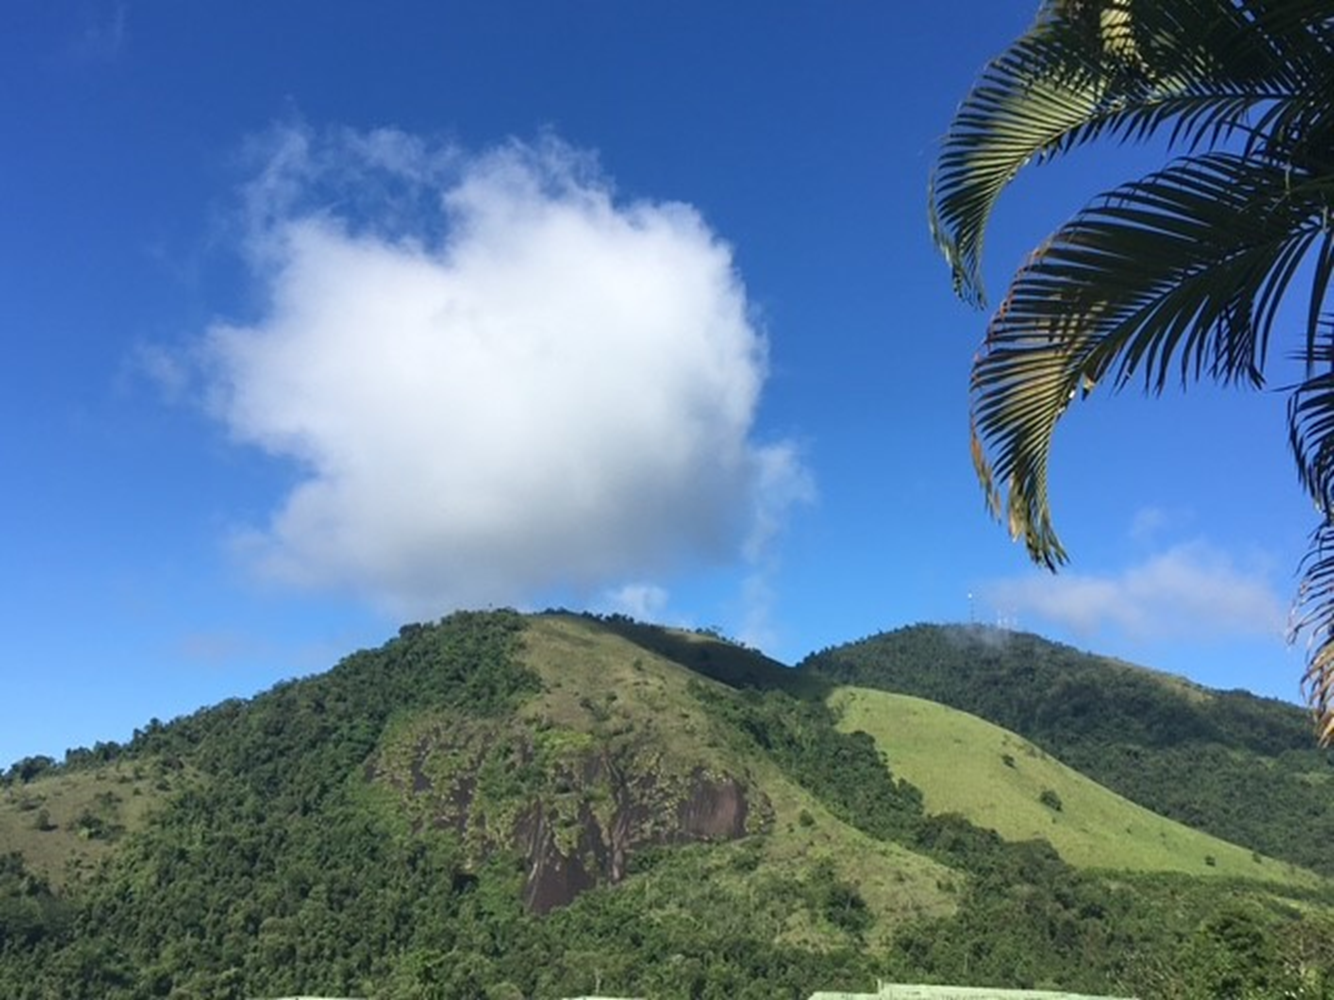

**Solution:**

CheckAnswer("exercise3","Select")

## Glossary

**k-means clustering**: an algorithm used to partition data into k*k* distinct clusters, where k*k* is a user-defined number. It aims to find centroids that represent different groups within the data. ↑ Return to Text

**graph-cut segmentation**: an algorithm that represents an image as a graph, with pixels as nodes and edges connecting them. Edges may have weights indicating pixel similarity. The goal is to partition the graph into segments by cutting edges, grouping similar pixels together, and classifying them into foreground and background regions. ↑ Return to Text

**histogram-based segmentation**: a technique that segments an image by analyzing pixel intensity histograms and identifying thresholds to separate regions.  ↑ Return to Text

[⇦ Return to the main menu](matlab:open('..\MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function CheckAnswer(exerciseID, option) % Function to check answers for exercises
% Reshape image into Nx3 matrix (rows: pixels, cols: La*b*)
% k is the number of clusters
[X,Y,Z] = size(ImgDouble);
pixels = reshape(ImgDouble,X*Y,Z);

% Apply k-means clustering
[idx,centroids] = kmeans(pixels,k,Replicates=3);

% Plot clusters in a 2D scatter plot
figure;
gscatter(pixels(:,2),pixels(:,3),idx);
hold on;

% Plot centroids of the clusters
scatter(centroids(:,2),centroids(:,3),100,"black","x",LineWidth=2);

% Set labels and title for the 2D plot
xlabel("a* Channel");
ylabel("b* Channel");
title("Scatter Plot of Clusters and Centroids");

% Create legend entries for each cluster and centroids
legendEntries = cell(k+1,1);
for i = 1:k
    legendEntries{i} = "Cluster "+num2str(i);
end
legendEntries{k+1} = "Centroids";
legend(legendEntries,Location="bestoutside");
hold off;
end

function SegmentedImg= VizClust(ClustImg,L,TargetCluster)
% Create a binary mask
% mask = reshape(idx == TargetCluster, X, Y);
mask = L == TargetCluster;

% Apply mask to the original image
SegmentedImg = ClustImg;
SegmentedImg(repmat(~mask,[1,1,3])) = 0;

% Display segmented image
montage({labeloverlay(ClustImg,L);SegmentedImg},Size=[1,2])
end


function CheckAnswer(exerciseID, option)
% Define the structure for each exercise (answers and hints)
exercises = struct( ...
    "exercise1", struct("answer","[115,120]","hint","Which pixel intensity correlates with gray?"),...
    "exercise2", struct("answer","Three","hint","Which cluster has the greatest mean silhouette value?"),...
    "exercise3", struct("answer","Graph-Cut","hint","Which technique is best for isolating specific objects?")...
    );
% Check if the exercise exists
if isfield(exercises,exerciseID)
    CorrectAnswer = exercises.(exerciseID).answer;
    hint = exercises.(exerciseID).hint;

    % Compare answers
    if isequal(option,CorrectAnswer)
        disp("You are correct.");
    elseif isequal(option,"Select")
        warning("Select a valid option.")
    else
        warning("%s",hint);
    end
else
    warning("Exercise not found.");
end
end

function [PixSamp,idx] = PlotKClust(ImageR,k) % Function to perform k-means clustering and plot results in a scatter plot
% Convert image to Lab color space
ImageRL = rgb2lab(ImageR);

% Convert to double precision for processing
ImageRDouble = im2double(ImageRL);

% Get image dimensions
[X,Y,Z] = size(ImageRDouble);

%  Reshape the image into an (X*Y) × 3 matrix (each row is a pixel, each column is a color channel)
pixels = reshape(ImageRDouble,X*Y,Z);

% Downsample pixels if necessary
MaxSamp = 10000; % Set a limit on how many pixels to use for silhouette
NumPix = size(pixels,1);
if NumPix > MaxSamp
    RandIdx = randperm(NumPix,MaxSamp); % Randomly select samples
    PixSamp = pixels(RandIdx,:);
else
    PixSamp = pixels;
end

% Run K-means clustering
[idx,centroids] = kmeans(PixSamp,k,Replicates=3);

%  Plot K-means clusters in a 2D scatter plot
figure;
gscatter(PixSamp(:,2),PixSamp(:,3),idx);
hold on;

%  Plot centroids of the clusters
scatter(centroids(:,2),centroids(:,3),100,"k","x",LineWidth=2);

% Set labels and title for the 2D plot
xlabel("a* Channel");
ylabel("b* Channel");
title("Scatter Plot of Clusters and Centroids");

% Create legend entries for each cluster and centroids
legendEntries = cell(k+1,1);
for i = 1:k
    legendEntries{i} = "Cluster "+num2str(i);
end
legendEntries{k+1} = "Centroids";
legend(legendEntries,Location="bestoutside");
hold off;
end

function DispHist(Range,ToyG,BinSz) % Function to display histogram
if ~strcmp(Range,"Select")
    Range = str2num(Range);
    histogram(ToyG,BinLimits=Range,BinWidth=BinSz);
    xlabel("Pixel Intensity")
    ylabel("Counts")
    axis padded
    ax2 = gca;
    ax2.PositionConstraint = "outerposition";
    xlim(Range); % Zoom in on the intensity range 100 to 150
    ylim([0 8000]); % Keep y-axis limits the same
else
    warning("Select a valid option.")
end
end

function HistDisp(Image) % Function to display a histogram with a grayscale colorbar
histogram(Image)
xlabel("Intensity Range")
ylabel("Counts")
axis padded
ax = gca;
ax.PositionConstraint = "outerposition";
colormap("gray")
colorbar(ax,Ticks=[0,0.5,1],TickLabels={"Black","Gray","White"},Location="southoutside")

end